# Introduction to MATLAB

In this document we will cover the basics of Syntax.

MATLAB is a command-based language, which means that all work done in MATLAB is done by sequentially sending commands to the MATLAB interpreter. All commands can be written either directly into the command window or in a text-based file which can be called from the Command Window (see below). Commands that are run from a text-based file are run from top to bottom (generally speaking, there are some caveats). Let's jump in.

## Desktop Basics

We will begin by defining a few components of the MATLAB desktop, which we will refer to often.

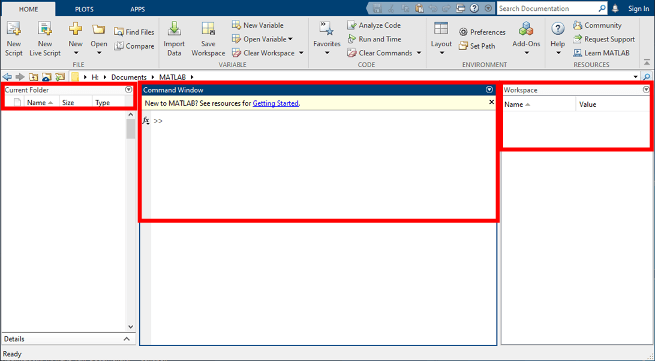

In the above diagram, 3 of the 4 main panels are highlighted in red.

- Current Folder - Access your files. This is the **Working Directory**. MATLAB can see any files placed here and the location is shown in the location bar above.

- Command Window - Enter commands at the command prompt (Indicated by `>>`). The command window also displays any output text or information from running commands.

- Workspace - Explore data you craete or import. Here are the variables available in the global scope (scoping will be discussed later).

### Running Commands

Running commands in this live script is the same as running commands directly in the command Window. As you work in MATLAB, the commands you issue may call functions, create variables, and change variables. For example, the following statement (command) will create a variable named `myNum`, and the variable will store the numeric value, 1.

myNum = 1

someResult = 0.7456

First select this section by clicking here. Then, on the Live Editor tools tab, you can clik on "run this section" (or press Ctrl+Enter or Cmd+Return) to see what the outcome is. Or you can copy and paste the command into the Command Window and press Enter/Return. 

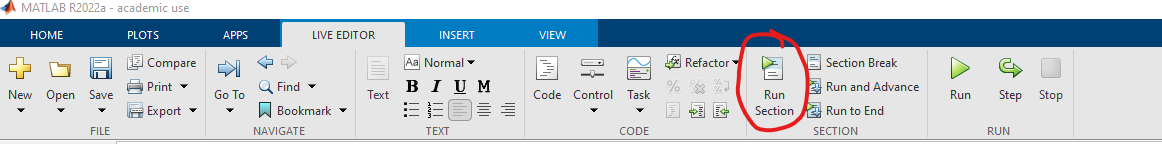

### Using Variables

We can do further operations with the value in our variable by simply referring to the variable name.

incrementedNum = myNum + 1;

*Tip: Suppress the output by placing a semi-colon (;) at the end of your statement. You can verify the computation complete by simply referring to the variable name.

incrementedNum

*Run this section

### The Editor

The fourth component of the MATLAB desktop interface is the Editor. We will mostly work in the editor and the Command Window for all analyses. When a new script, function, or class file is created, or when one is opened, it will be displayed in a tab within the editor panel. In fact, this document is a live script, which is functionally similar to script-files and function-files, but has an element of interactivity. Live script files are useful for tutorials and short reports as they can run code and display results. However, we will almost never use them except in the case of a tutorial. For our purposes, we will primarily use script-files to organize final analyses and generate figures. We will primarily use functions to create analysis routines and tools that can be reused and shared easily. A main goal of this educational series is to convince you to use a particular philosophy when analyzing your data. As we go along, we will make pointed remarks to guide your understanding and instill a best-practice mindset. We also aim to provide you the tools and framework necessary for you to expand upon and build your own style and practices. 

## Syntax Basics

In this section we will cover the important aspect of the MATLAB language that allows one to actually work towards a goal. Just like learning a spoken language, we must know how statements are strung together, how statements are terminated, and what order operations may take.

### Continuing Statements

When writing a long statement, we may come to a point where the readability is affected by having to scroll horizontally. MATLAB provides a simple syntax for breaking long statements onto multiple lines so MATLAB can interpret the statement correctly. In the following example we will break a long statement using the ellipsis operator (...).

someResult = 1 - 1/2 + 1/3 - 1/4 + 1/5 ...
  - 1/6 + 1/7 - 1/8 + 1/9

Depending on your MATLAB preferences, after typing the ellipsis and pressing enter, your code should indent by 2 or 4 spaces. If you ever use code written by someone else, it will likely have either 2 or 4 spaces for every indentation level. We can use the ellipsis to make long statements more readable. Consider the following statement:

sequence = 'GATAGATARCG';
validLetters = sequence=='A'|sequence =='T'|sequence=='C'|sequence=='G';

Even though this statement fits nicely on a single line, if you have 2 or more statements like this and a smattering of comments, this would become all but entirely unreadable. We can use the ellipsis to improve the readability like so:

validLetters = ...

ans = 5

  sequence == 'A' | ...
  sequence == 'T' | ...
  sequence == 'C' | ...

ans =     10     6     5


  sequence == 'G';

Now it is more clear that the sequence of characters being stored in the `sequence` variable are being compared to a set of valid characters.

### Call Functions

In MATLAB we "call" functions using parentheses to enclose input arguments and square brackets ('[',']') to enclose output arguments (when more than 1 output argument exists). If a function has no required input arguments, we can call the function in the command form, that is without the parentheses. For example:

% Create two numeric arrays
A = [1,3,5];

maxA = 5

B = [10,6,4];

% Enclose inputs to functions in parentheses:

maxA = 5

location = 3

max(A)

% Separate multiple inputs with commas:
max(A,B)

% Store output from a function by assigning it to a variable:
maxA = max(A)

% Enclose multiple outputs in square brackets:
[maxA, location] = max(A)

% Call a function that does not require any inputs, and does not return any outputs, by
% typing only the function name:
clc

### Ignoring Ouput

Whether built-in or user-created, some functions in MATLAB may have 0 or more outputs. It is possible to ignore some of the outputs using the `~` character. 

helpFile = which('help');

% Request all outputs from fileparts function
[fileRoot,fileName,fileExt] = fileparts(helpFile);

% Ignore the first output
[~,fileName,fileExt] = fileparts(helpFile);

% Ignore the first and second outputs
[~,~,fileExt] = fileparts(helpFile);

% Ignore the last output
[fileRoot,fileName,~] = fileparts(helpFile);

ans = 20×1 cell array
    {'break'     }
    {'case'      }
    {'catch'     }
    {'classdef'  }
    {'continue'  }
    {'else'      }
    {'elseif'    }
    {'end'       }
    {'for'       }
    {'function'  }
    {'global'    }
    {'if'        }
    {'otherwise' }
    {'parfor'    }
    {'persistent'}
    {'return'    }
    {'spmd'      }
    {'switch'    }
    {'try'       }
    {'while'     }



% To get only the first output, we can omit the other two altogether

ans = 0

fileRoot = fileparts(helpFile);

### Naming Variables

It is good to stick to a naming scheme. Typically I (Khris) use a scheme called camelCase because it is easy to type and read. With camelCase as the base scheme, I will often make function names with a starting upper case letter, variables with a starting lower case letter, and other variable types (globals, contants, persistent, etc.) in all caps snake_case. If you choose not to use this scheme I've outlines, it is imperitive that you choose a scheme and be consistent.

When naming variables, the best practice is to give meaningful, concise names. MATLAB imposes a few rules that ensure you have a valid variable name for the parser. MATLAB states, "A valid variable name starts with a letter, followed by letters, digits, or underscores. MATLAB is case sensitive, so A and a are not the same variable. The maximum length of a variable name is the value that the `namelengthmax` command returns.". You also cannot define variables with the same name as a keyword. A litst of MATLAB keywords are found with the `iskeyword` command:

iskeyword

y = 1.8370e-16

It is also good practice to not overwrite the name of an existing function. You can query if your desired variable name exists as a function in the following way:

exist('desiredVariableName','builtin')

y = 1.8370e-16

In MATLAB, a 0 is the same as `false` and 1 the same as `true.`

### Case And Space Sensitivity

MATLAB code is sensitive to casing, and insensitive to blank spaces except when defining arrays. 

#### Uppercase and Lowercase 

In MATLAB code, use an exact match with regard to case for variables, files, and functions. For example, if you have a variable, a, you cannot refer to that variable as A. It is a best practice to use lowercase only when naming functions. This is especially useful when you use both Microsoft® Windows® and UNIX®1 platforms because their file systems behave differently with regard to case. When you use the help function, the help displays some function names in all uppercase, for example, `PLOT`, solely to distinguish the function name from the rest of the text. Some functions for interfacing to Oracle® Java® software do use mixed case and the command-line help and the documentation accurately reflect that. 

#### Spaces 

Blank spaces around operators such as -, :, and ( ), are optional, but they can improve readability. For example, MATLAB interprets the following statements the same way. 

y = sin ( 3 * pi ) / 2 

A =      1     0     2     3     3


y=sin(3*pi)/2 

However, blank spaces act as delimiters in horizontal concatenation. When defining row vectors, you can use spaces and commas interchangeably to separate elements:

A = [1, 0 2, 3 3]

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

A = 1 0 2 3 3 

ans =    1.000000000000000   0.000000000000000   3.000000000000000


Because of this flexibility, check to ensure that MATLAB stores the correct values. For example, the statement `[1 sin (pi) 3]` produces a much different result than `[1 sin(pi) 3]` does. 

[1 sin(pi) 3]

Error using sin
Not enough input arguments.

[1 sin (pi) 3]

## Conclusions

Syntax refers to the rules that define the structure of a language. In computer programming, syntax refers to the rules that control th structure of the symbols, punctuation, and statements of the language. We saw above that certain operators like brackets and characters like spaces can have an impact on how the MATLAB interpreter "runs" the code. Without syntax, it is nearly impossible to understand the semantics of coded statements. We introduced the basics of the MATLAB language and highlighted a few features of the interpreter. We will continue to use these principals as we progress to more and more complex operations and analyses.